close all
clear all
clc

% define filter
tau = 1;
wc = 1/tau;


q = 5;%1/sqrt(2); % butterworth

s = tf('s');

h = (wc)/(wc+s)

h =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties



%bode(h)

% discretize filter
fs = 50e6

fs = 50000000

ts = 1/fs;

hz = c2d(h,ts,'tustin')

hz =
 
  1e-08 z + 1e-08
  ---------------
       z - 1
 
Sample time: 2e-08 seconds
Discrete-time transfer function.
Model Properties




alpha = cos(wc)

alpha = 0.5403

fc = 50000;
fs = 100000;
ts = 1/fs

ts = 1.0000e-05

wc = fc/fs*2*pi

wc = 3.1416

Omegac = tan(wc/2)

Omegac = 1.6331e+16


s = tf('s');
Han = 1/(1+s/Omegac)

Han =
 
    1.633e16
  ------------
  s + 1.633e16
 
Continuous-time transfer function.
Model Properties


hz = c2d(h,2,'tustin')

hz =
 
  0.5 z + 0.5
  -----------
       z
 
Sample time: 2 seconds
Discrete-time transfer function.
Model Properties


fs = 100e6;
shift = 20

shift = 20

maxshift = 24

maxshift = 24

alpha = 2^(shift-maxshift)

alpha = 0.0625

pyrplnum = [0 0 alpha];
pyrplden = [1 -1 alpha];
pyrpl = dsp.IIRFilter('Numerator',pyrplnum,'Denominator',pyrplden);
stnum = [alpha];
stden = [1 -(1-alpha)];
std_iir = dsp.IIRFilter('Numerator',stnum,'Denominator',stden);
tustin_num = alpha/2*[1 1];
tustin_den = [1 -(1-alpha)];
tustin_iir = dsp.IIRFilter('Numerator',tustin_num,'Denominator',tustin_den);
tustin_lat_num = alpha/2*[0 1 1];
tustin_lat_den = [1 -(1-alpha)];
tustin_lat_iir = dsp.IIRFilter('Numerator',tustin_lat_num,'Denominator',tustin_lat_den);

downsapler = dsp.FIRDecimator(2, [1 0])

downsapler =   dsp.FIRDecimator with properties:

   Main
    DecimationFactor: 2
     NumeratorSource: 'Property'
           Numerator: [1 0]
           Structure: 'Direct form'

  Show all properties


%tustin_second_order = dsp.FilterCascade(tustin_iir,tustin_iir);
%tustin_num_unwrap = [alpha/2 (alpha-(alpha^2)/2) (alpha-alpha^2)/2]
%tustin_den_unwrap = [1 0 -(1-alpha)^2]
%tustin_iir_unwrap = dsp.IIRFilter('Numerator',tustin_num_unwrap,'Denominator',tustin_den_unwrap)
 

tustin_num_down = alpha*[0 1 1];
tustin_den_down = [1 -(1-alpha*2)];
tustin_iir_down = dsp.IIRFilter('Numerator',tustin_num_down,'Denominator',tustin_den_down);
tustin_iir_2slow = dsp.FilterCascade(downsapler,tustin_iir_down);
fvtool(pyrpl, tustin_lat_iir, tustin_iir_2slow, 'Fs',fs)

%%calculate wc from alpha, alpha = 1-(1-sin(wc))/cos(wc);
wc = asec((-alpha^2 + 2*alpha-2)/(2*(alpha-1)));
fc=wc/(2*pi)*fs

fc = 1.0265e+06

tau=1/(2*pi*fc)

tau = 1.5505e-07

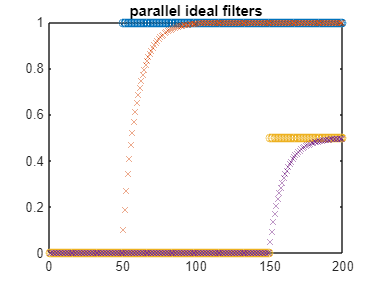

%%test multiple input implementation

x1 = [zeros(1,50) ones(1,150)]; %create a step function
x2 = 0.5*[zeros(1,150) ones(1,50)]; %create a step function

y1 = zeros(1,200);
y2 = zeros(1,200);

for i=2:length(x1)
    y1(i) = 0.9*y1(i-1)+0.1*x1(i);
    y2(i) = 0.9*y2(i-1)+0.1*x2(i);
end
figure()
plot (x1,'o');
hold on;
plot (y1,'x');
plot (x2,'o');
plot (y2,'x');
title('parallel ideal filters')
hold off;

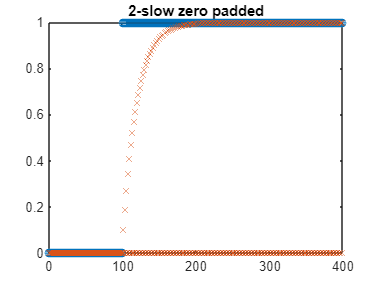


%% alternating input zero or valid data (it has to work at double the clock)

x1ext=repelem(x1,2);
y1ext=repelem(y1,2);
for i=3:length(x1ext)
    if(rem(i,2)==0)
        y1ext(i) = 0.9*y1ext(i-2)+0.1*x1ext(i);
    else
        y1ext(i) = 0.9*y1ext(i-2)+0.1*0;
    end
end
figure()
plot (x1ext,'o');
hold on;
plot (y1ext,'x');
title('2-slow zero padded')

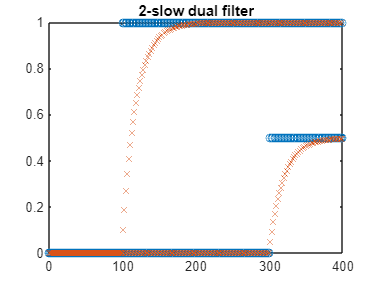


%% alternating inputs (it has to work at double the clock)

temp = [x1;x2];
alter_x=temp(:)';
alter_y=zeros(1,length(alter_x));
for i=3:length(alter_x)
    alter_y(i) = 0.9*alter_y(i-2)+0.1*alter_x(i);
end
figure()
plot (alter_x,'o');
hold on;
plot (alter_y,'x');
title('2-slow dual filter')

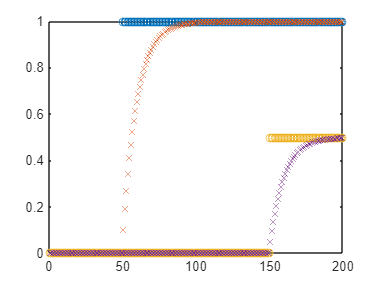



%% Deserialize the data from the filter

x1_ext = alter_x(1:2:end);
x2_ext = alter_x(2:2:end);
y1_ext = alter_y(1:2:end);
y2_ext = alter_y(2:2:end);

figure()
plot (x1_ext,'o');
hold on;
plot (y1_ext,'x');
plot (x2_ext,'o');
plot (y2_ext,'x');
hold off;

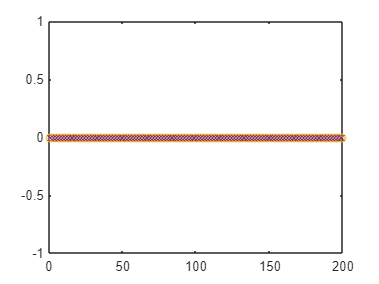


%% Is the same as the single implementation

figure()
plot (x1-x1_ext,'o');
hold on;
plot (y1-y1_ext,'x');
plot (x2-x2_ext,'o');
plot (y2-y2_ext,'x');
hold off;

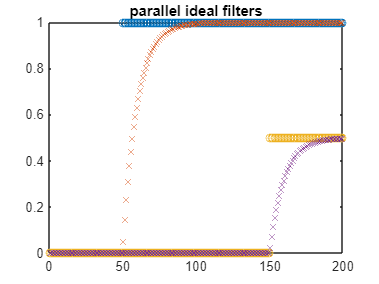

%%test multiple input implementation

x1 = [zeros(1,50) ones(1,150)]; %create a step function
x2 = 0.5*[zeros(1,150) ones(1,50)]; %create a step function

y1 = zeros(1,200);
y2 = zeros(1,200);

for i=2:length(x1)
    y1(i) = y1(i-1)+0.1*((x1(i)+x1(i-1))/2 - y1(i-1));
    y2(i) = y2(i-1)+0.1*((x2(i)+x2(i-1))/2 - y2(i-1));
end
figure()
plot (x1,'o');
hold on;
plot (y1,'x');
plot (x2,'o');
plot (y2,'x');
title('parallel ideal filters')
hold off;

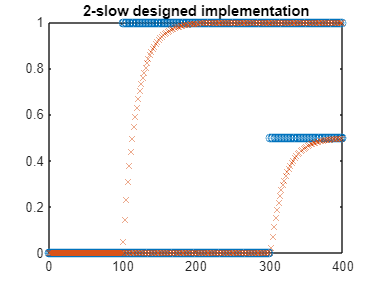


%% alternating inputs real implementation (it has to work at double the clock)

temp = [x1;x2];
alter_x=temp(:)';
alter_y=zeros(1,length(alter_x));
sum1 = alter_y;
sum2 = alter_y;
sum3 = alter_y;
product1 = alter_y;
for i=3:length(alter_x)
    sum1(i) = 1/2*(alter_x(i) + alter_x(i-2));
    sum2(i) = sum1(i) - alter_y(i-1);
    product1(i) =  sum2(i-1) * 0.1;
    sum3(i) = product1(i)+sum3(i-2);
    alter_y(i) = sum3(i);
end
figure()
plot (alter_x,'o');
hold on;
plot (alter_y,'x');
title('2-slow designed implementation')

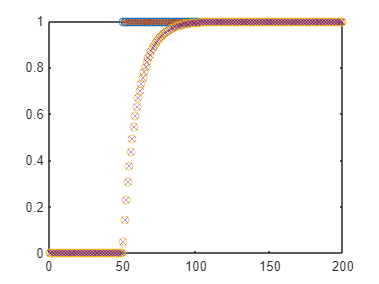


%% Deserialize the data from the filter
%Increased latency by one, so y1 and 2 switched

x1_ext = alter_x(1:2:end);
x2_ext = alter_x(2:2:end);
y2_ext = [alter_y(1:2:end)];
y1_ext = [alter_y(2:2:end)];


%% Is the same as the single implementation

figure()
plot (x1,'o');
hold on;
plot (x1_ext,'x');
plot (y1,'o');
plot (y1_ext,'x');
hold off;

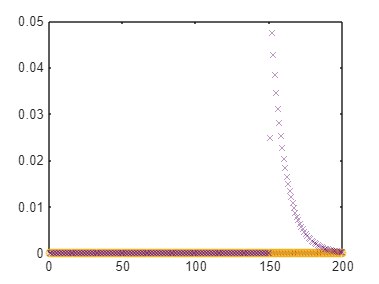



%% Is the same as the single implementation

figure()
plot (x1-x1_ext,'o');
hold on;
plot (y1-y1_ext,'x');
plot (x2-x2_ext,'o');
plot (y2-y2_ext,'x');
hold off;